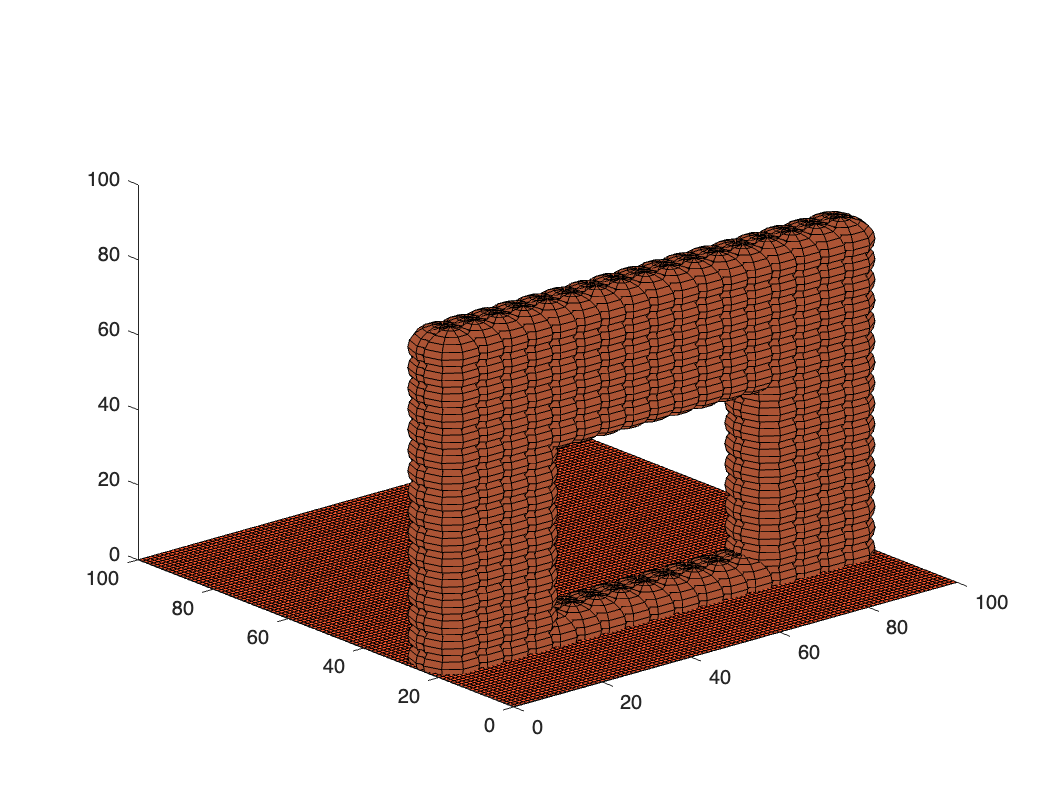

% Demonstration script for the 3D course planning software

% Create a new world and add obstacles to it 
space = world(100, 100, 100, Obstacle.empty);
%space = add_arch(space, [50 75 0], 30, 80, 10);
%space = add_terrain(space, 150, 3);
%space = add_wall(space, 20, 80, 40, 50, -10, 60, 6);
space = add_holy_wall(space, 0, 100, 20, 30, -10, 90, 6, [50 20 30], 25);
plot_world(space);


% Define the Helicopter dimension as a min clearance from obstacle
clearance = 10;

% Create a PRM planner over the space for the helicopter
planner = PRM(200, 10, space, clearance);

% Sample the space and populate the edges in the graph
u_sampled = sampler(planner);
show_sample(u_sampled);
title('Uniformly sampled space')
u_sampled = create_edges(u_sampled);
show_graph(u_sampled)
title('Graph for uniformly sampled space')

% Now make a copy of the planner in which we have solved for a path
start = [45 1 70];
goal = [95 95 20];
mapped = find_path(u_sampled, start, goal);

% Show the path
show_path(mapped);
title('Path found using uniform sampler')

% Do post-processing
mapped = post_process(mapped);
show_path(mapped);
title('Path found using uniform sampler')

% Try smoothing
mapped = smooth_path(mapped);
show_smooth(mapped);
title('Path found using uniform sampler')

% Now try an adaptive sampler
a_sampled = adaptive_sampler(planner, start, goal, 10);
show_sample(a_sampled);
title('Adaptively sampled space')

% Connect up the graph
a_sampled = create_edges(a_sampled);
show_graph(a_sampled);
title('Graph for adaptively sampled space')

% Find a path from start to goal
mapped = find_path(a_sampled, start, goal);
show_path(mapped);
title('Path found by adaptive sampler')

% Perform post-processing
mapped = post_process(mapped);
show_path(mapped);
title('Path found by adaptive sampler')

% Try smoothing
mapped = smooth_path(mapped);
show_smooth(mapped);
title('Path found by adaptive sampler')
